# Forecasting of coronavirus COVID19 epidemic (SIR model)

It is assumed that the model is a reasonable description of the one-stage epidemic. In particular, the model assumes a constant population, uniform mixing of the people, and equally likely recovery of infected. The model is data-driven, so its forecast is as good as data are. The forecasting change with new or changed data.

**DISCLAIMER**: Software and data is for education and not for medical or commercial. The model may fail in some situations. In particular, the model may be unadequate, the model may fail in the initial phase and in when additional epidemic stages or outbreaks  (not described by SIR model) are encountered. Use it at your own discretion.

**Source of data**

[https://ourworldindata.org/coronavirus-source-data.](https://ourworldindata.org/coronavirus-source-data.)

[https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina](https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina)

[https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory](https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory)

An actual source of data is for each country reported in the corresponding getData function.

**Report**

fprintf('Date: %s\n',datestr(date))  

Date: 26-Mar-2020


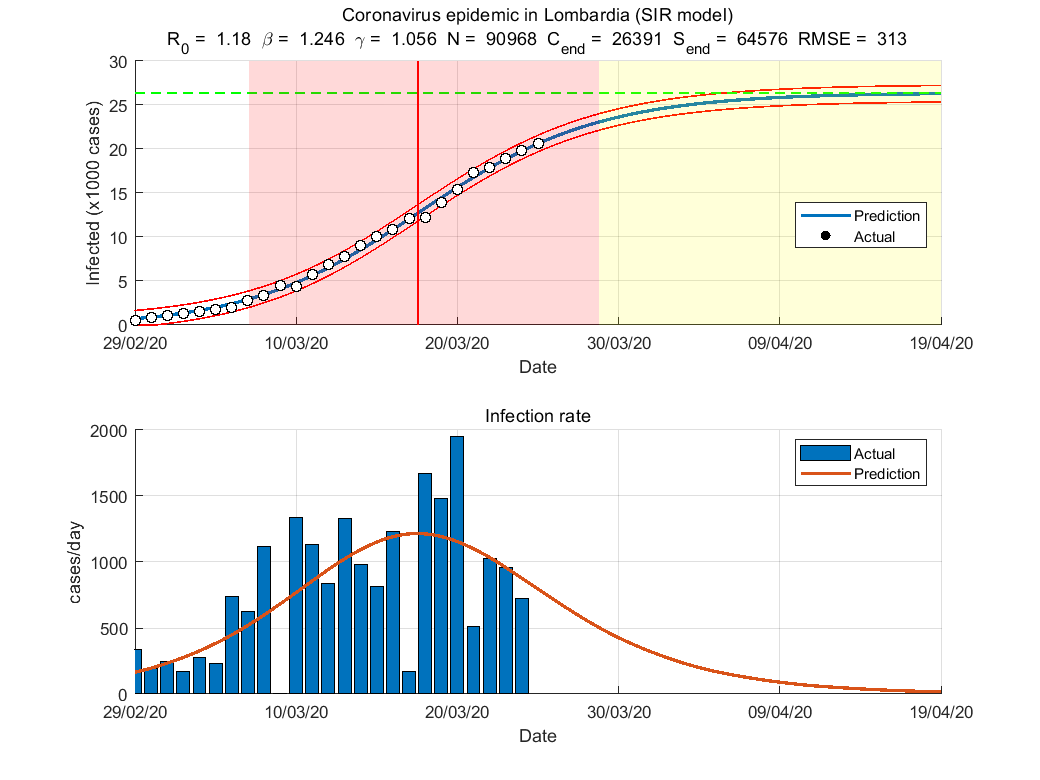

Epidemic modeling by susceptible-infected-recovered (SIR) model
  Country                       Lombardia
  Day                           34
Estimated the SIR model parameters
  Contact rate (beta)           1.246 (1/day)
  Removal rate (gamma)          1.056 (1/day)
  Population size (N)           90967
  Initial number of cases (I0)  29
Basic reproduction number (R0)  1.18
Final state
  Final number of cases         26391
  Final number of susceptibles  64576
Daily forcast for 26-Mar-2020
  Total                         21366
  Increase                      758
Estimated logistic model parameters
  Epidemic size (K)             24076 (cases)
  Epidemic rate (r)             0.190105 (1/day)
  Initial doubling time         3.6 (day)
Estimated duration (days)
  Turning day                   26
  Acceleration   phase          10 (days)
  Deaceleration  phsee          11 (days)
  Total duration                22 (days)
Estimated datums
  Outbreak                      21-Feb-2020
  Start o

aut = fitVirusCV19(@getDataLombardia,'prn','on','nmax',1e5);